**Global Barycentric 1 Interpolation**

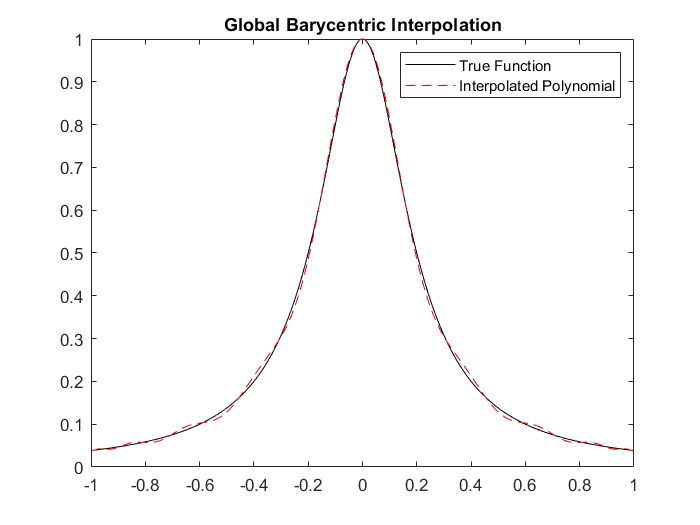

% Function
k=25;
f = @(x) 1 ./ (1+k*x.^2);      % Runge Function

% Parameters
n = 20;
a = -1;
b = 1;
node_type = 'chebyshev2';

ncheck = 1000;
xcheck = linspace(a, b, ncheck)';

% This in addition returns kappa_numer and lebesgue_vals (remove ~)
[pvals, ftruevals, ~, ~] = global_p(f, xcheck, a, b, n, node_type);

% Visualization
plot(xcheck, ftruevals, 'k-', xcheck, pvals, 'r--');
legend('True Function', 'Interpolated Polynomial');
title('Global Barycentric Interpolation');

**Piecewise Newton Interpolation**

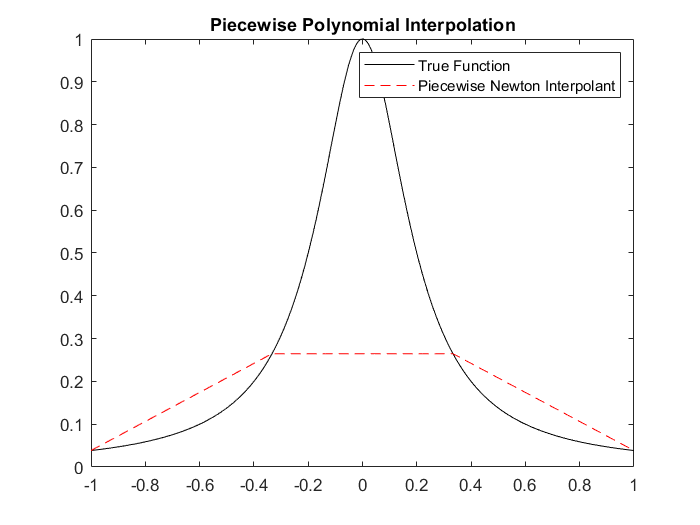

% Parameters
num_intervals = 7;
a = -1;
b = 1;
global_mesh = linspace(a,b,num_intervals+1);
s = 1;                          % Degree of local Interpolant
node_type = 'chebyshev2';       % chebyshev2 or uniform

f_prime = @(x) (-k*x) ./ ((1+k*x.^2).^2) ; 
hermite_flag = true;

ncheck = 1000;
xcheck = linspace(a, b, ncheck)';
[divdiffs, local_meshes] = local_divdiffs(f, global_mesh, s, node_type, false, f_prime);
pvals = piecewise_p(xcheck, global_mesh, divdiffs, local_meshes, num_intervals, false);

ftrue = f(xcheck);


[divhermite, localhermite] = local_divdiffs(f, global_mesh, 3,'uniform', hermite_flag,f_prime);
pvals_hermite =  piecewise_p(xcheck, global_mesh, divhermite, localhermite, num_intervals,hermite_flag);


% Visualization
plot(xcheck, ftrue, 'k-', xcheck, pvals, 'r--');
legend('True Function', 'Piecewise Newton Interpolant');
title('Piecewise Polynomial Interpolation');

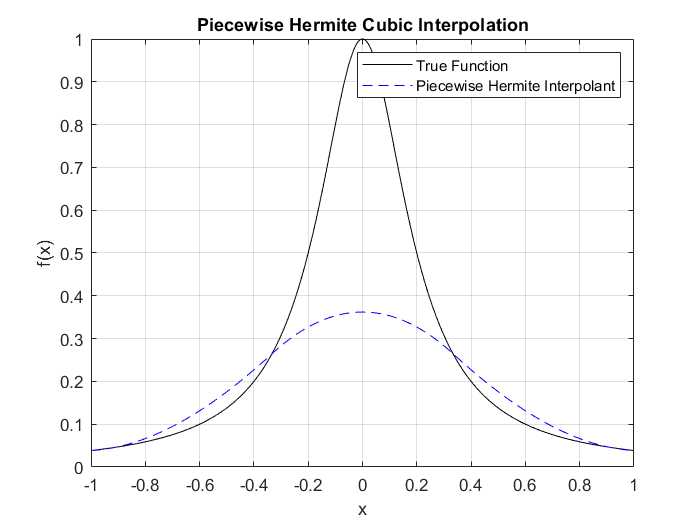



% Visualization for Hermite Interpolation
figure;
plot(xcheck, ftrue, 'k-', xcheck, pvals_hermite, 'b--');
legend('True Function', 'Piecewise Hermite Interpolant');
title('Piecewise Hermite Cubic Interpolation');
xlabel('x');
ylabel('f(x)');
grid on;

**Cubic Spline 1 (first derivatives parameterization)**

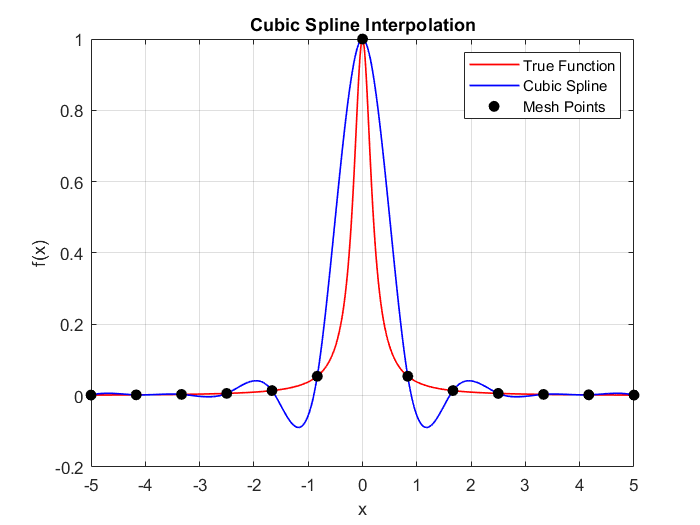

% Replace with an arbitrary non-uniform mesh
a = -5;
b = 5;
num_intervals = 12;     % Keep even for Runge Function
global_mesh = linspace(a,b,num_intervals+1);
%global_mesh = [-5,-2.5,0,1,2,2.5,5];
bd_type = 'first';
% Define first derivative boundary conditions [s_0', s_n']
boundary_conditions = (1/26^2) * [25, -25];

fvals = f(global_mesh);

% Compute the spline first derivative solution
s_prime = cubic_spline_first_derivatives(global_mesh, fvals, boundary_conditions, bd_type);

% Define xcheck points for evaluation
xcheck = linspace(-5, 5, 1000);

% Evaluate the cubic spline
spline_vals = cubic_spline(global_mesh, fvals, s_prime, xcheck);

true_vals = f(xcheck);

% Plot results
figure;
plot(xcheck, true_vals, 'r-', 'LineWidth', 1); hold on;
plot(xcheck, spline_vals, 'b-', 'LineWidth', 1);
plot(global_mesh, f(global_mesh), 'ko', 'MarkerFaceColor', 'k'); % Mesh points
legend('True Function', 'Cubic Spline', 'Mesh Points');
xlabel('x');
ylabel('f(x)');
title('Cubic Spline Interpolation');
grid on;
hold off;

**Cubic Spline 2 (B-spline basis parameterization)**

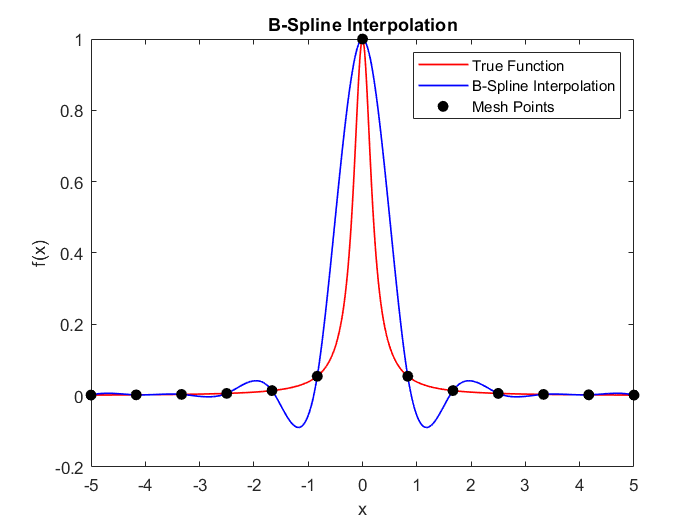

% Parameters
num_intervals = 12; 
a = -5;
b = 5;
global_mesh = linspace(a,b, num_intervals + 1); % n+1 points
bd_type = 'first';

h = 1.0 *((b - a) / num_intervals); % Compute h from interval length
xcheck = linspace(a, b, 1000);
% Compute B-spline coefficients (alpha) using B_spline_alpha
boundary_conditions = (1/26^2) * [25, -25];

fvals = f(global_mesh);
alpha = B_spline_alpha(global_mesh, fvals, boundary_conditions, h, bd_type);

spline_vals = B_spline(xcheck, alpha, global_mesh);

true_vals = f(xcheck);

% Plot results
figure;
plot(xcheck, true_vals, 'r-', 'LineWidth', 1); hold on;
plot(xcheck, spline_vals, 'b-', 'LineWidth', 1);
plot(global_mesh, f(global_mesh), 'ko', 'MarkerFaceColor', 'k'); % Mesh points
legend('True Function', 'B-Spline Interpolation', 'Mesh Points');
xlabel('x');
ylabel('f(x)');
title('B-Spline Interpolation');

**Task 2**

% Time values (t_i)
t = [0.5, 1.0, 2.0, 4.0, 5.0, 10.0, 15.0, 20.0];

% Corresponding y values (y(t_i))
y = [0.04, 0.05, 0.0682, 0.0801, 0.0940, 0.0981, 0.0912, 0.0857];

a = 0.5;
b = 20;
numintervals = 7;
bd_type = 'second';
boundary_conditions = [0, 0];    % Natural Boundary Conditions

s_prime = cubic_spline_first_derivatives(t, y, boundary_conditions, bd_type);

% Define xcheck points for evaluation
tstep = 80 % (del(t) = 0.5 from 0.5 to 40)

tstep = 80

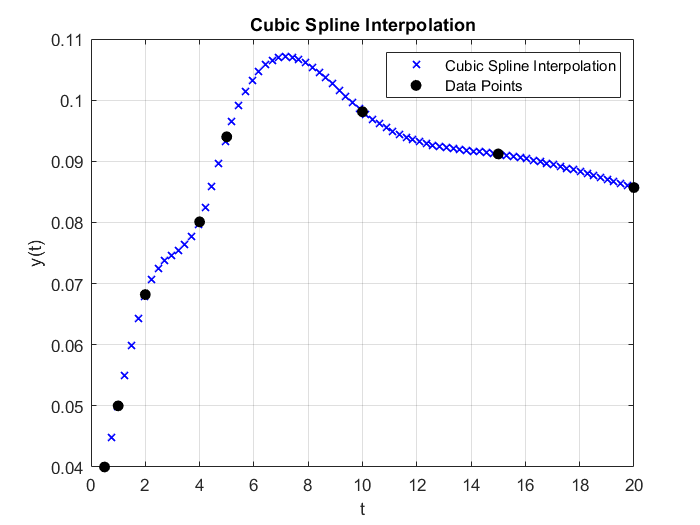

xcheck = linspace(a, b, 80);

% Evaluate the cubic spline
spline_vals = cubic_spline(t, y, s_prime, xcheck);

spline_deriv_vals = cubic_spline_derivative(t, y, s_prime, xcheck);

% ---- PLOT 1: Cubic Spline Interpolation ----
figure;
plot(xcheck, spline_vals, 'bx', 'LineWidth', 1); hold on;
plot(t, y, 'ko', 'MarkerFaceColor', 'k'); % Mesh points
legend('Cubic Spline Interpolation', 'Data Points');
xlabel('t');
ylabel('y(t)');
title('Cubic Spline Interpolation');
grid on;
hold off;

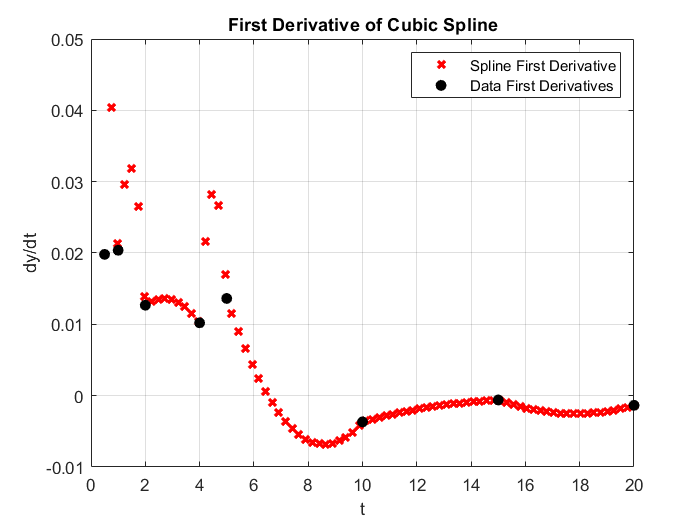


% ---- PLOT 2: First Derivative of the Spline ----
figure;
plot(xcheck, spline_deriv_vals, 'rx', 'LineWidth', 2); hold on;
plot(t, s_prime, 'ko', 'MarkerFaceColor', 'k'); % First derivative at known points
legend('Spline First Derivative', 'Data First Derivatives');
xlabel('t');
ylabel('dy/dt');
title('First Derivative of Cubic Spline');
grid on;
hold off;

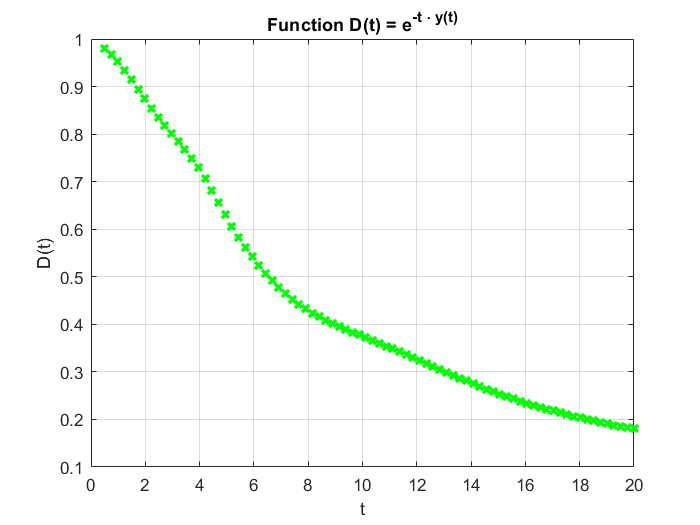



% Compute functions D(t) and f(t)
D_t = exp(-xcheck .* spline_vals);
f_t = spline_vals + xcheck .* spline_deriv_vals;

% ---- PLOT 3: Function D(t) = exp(-t * y(t)) ----
figure;
plot(xcheck, D_t, 'gx', 'LineWidth', 2);
xlabel('t');
ylabel('D(t)');
title('Function D(t) = e^{-t \cdot y(t)}');
grid on;

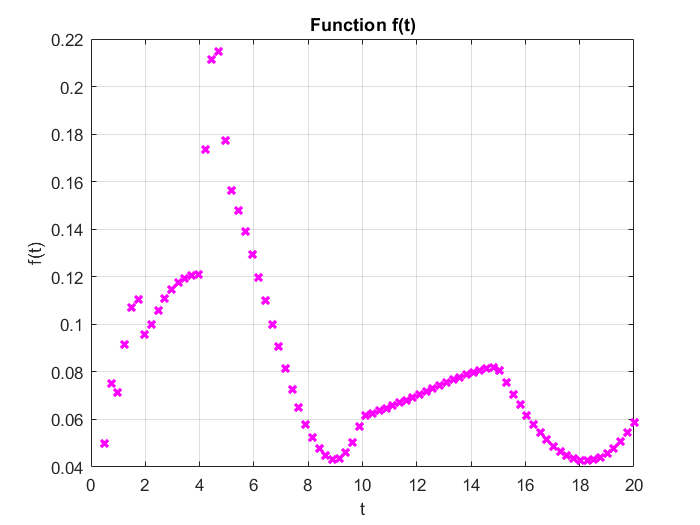


% ---- PLOT 4: Function f(t) = y(t) + t * y\'(t) ----
figure;
plot(xcheck, f_t, 'mx', 'LineWidth', 2);
xlabel('t');
ylabel('f(t)');
title('Function f(t)');
grid on;

Manually doing g_d interpolation for this task to see details

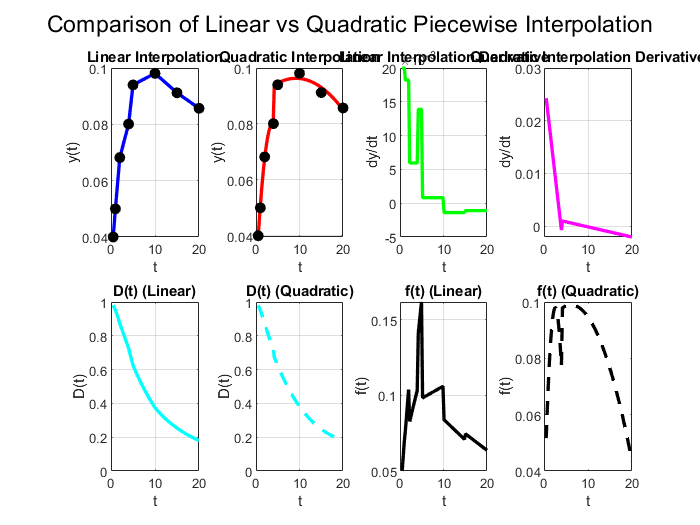

y_linear = zeros(size(xcheck));
y_linear_deriv = zeros(size(xcheck));
% Compute linear interpolants
for i = 1:length(t)-1
    idx = (xcheck >= t(i)) & (xcheck <= t(i+1));
    slope = (y(i+1) - y(i)) / (t(i+1) - t(i)); 
    y_linear(idx) = y(i) + slope * (xcheck(idx) - t(i));
    y_linear_deriv(idx) = slope;  % Constant derivative for linear function
end

% first 4 points for first quadratic
T1 = t(1:4)';
Y1 = y(1:4)';
A1 = [T1.^2, T1, ones(size(T1))] \ Y1 ;

% last 4 points for second quadratic
T2 = t(5:8)';
Y2 = y(5:8)';
A2 = [T2.^2, T2, ones(size(T2))] \ Y2; 

y_quad = zeros(size(xcheck));
y_quad_deriv = zeros(size(xcheck));
for i = 1:length(xcheck)
    if xcheck(i) <= t(4)
        y_quad(i) = A1(1)*xcheck(i)^2 + A1(2)*xcheck(i) + A1(3);
        y_quad_deriv(i) = 2*A1(1)*xcheck(i) + A1(2);
    else
        y_quad(i) = A2(1)*xcheck(i)^2 + A2(2)*xcheck(i) + A2(3);
        y_quad_deriv(i) = 2*A2(1)*xcheck(i) + A2(2);
    end
end
D_linear = exp(-xcheck .* y_linear);
f_linear = y_linear + xcheck.*y_linear_deriv;
D_quad = exp(-xcheck .* y_quad);
f_quad = y_quad +xcheck .* y_quad_deriv;

figure;
% ---- Row 1: Interpolated Function ----
subplot(2,4,1);
plot(xcheck, y_linear, 'b-', 'LineWidth', 2); hold on;
plot(t, y, 'ko', 'MarkerFaceColor', 'k');
xlabel('t'); ylabel('y(t)');
title('Linear Interpolation');
grid on;

subplot(2,4,2);
plot(xcheck, y_quad, 'r-', 'LineWidth', 2); hold on;
plot(t, y, 'ko', 'MarkerFaceColor', 'k');
xlabel('t'); ylabel('y(t)');
title('Quadratic Interpolation');
grid on;

% ---- Row 2: First Derivative ----
subplot(2,4,3);
plot(xcheck, y_linear_deriv, 'g-', 'LineWidth', 2);
xlabel('t'); ylabel("dy/dt");
title('Linear Interpolation Derivative');
grid on;

subplot(2,4,4);
plot(xcheck, y_quad_deriv, 'm-', 'LineWidth', 2);
xlabel('t'); ylabel("dy/dt");
title('Quadratic Interpolation Derivative');
grid on;

% ---- Row 3: Function D(t) = e^{-t * y(t)} ----
subplot(2,4,5);
plot(xcheck, D_linear, 'c-', 'LineWidth', 2);
xlabel('t'); ylabel('D(t)');
title('D(t) (Linear)');
grid on;

subplot(2,4,6);
plot(xcheck, D_quad, 'c--', 'LineWidth', 2);
xlabel('t'); ylabel('D(t)');
title('D(t) (Quadratic)');
grid on;

% ---- Row 4: Function f(t) = y(t) + t * y'(t) ----
subplot(2,4,7);
plot(xcheck, f_linear, 'k-', 'LineWidth', 2);
xlabel('t'); ylabel('f(t)');
title('f(t) (Linear)');
grid on;

subplot(2,4,8);
plot(xcheck, f_quad, 'k--', 'LineWidth', 2);
xlabel('t'); ylabel('f(t)');
title('f(t) (Quadratic)');
grid on;

% Adjust spacing
sgtitle('Comparison of Linear vs Quadratic Piecewise Interpolation');
grid off;
hold off;